现在是执行PCA算法

% 执行PCA
%绘制pca 之前的图像DA
data = zscore(data);
data2 =data';
figure;
%scatter(data2(:,1), data2(:,200), 10, groundTruth, 'filled');
% grid on
% title('raw data');
% xlabel('data(:,1)');
% ylabel('data(:,200)');

[coeff, score, ~] = pca(data2,"Centered",true,"Algorithm","svd","NumComponents",2);
% 选择前两个主成分进行降维
low_dim_data = score(:, 1:2);

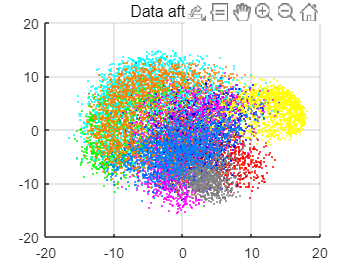


% 假设 groundTruth 包含从 1 到 9 的类别标签
% 创建一个 9x3 的颜色矩阵，每一行代表一个类别的颜色
colors = [1 0 0;  % 类别 1 的颜色 (红色)
          0 1 0;  % 类别 2 的颜色 (绿色)
          0 0 1;  % 类别 3 的颜色 (蓝色)


          1 1 0;  % 类别 4 的颜色 (黄色)
          1 0 1;  % 类别 5 的颜色 (品红)
          0 1 1;  % 类别 6 的颜色 (青色)
          0.5 0.5 0.5; % 类别 7 的颜色 (灰色)
          0 0.5 1;  % 类别 8 的颜色 (黑色)
          1 0.5 0]; % 类别 9 的颜色 (橙色)


% 使用 groundTruth 索引这个颜色矩阵
scatterColors = colors(groundTruth, :);

% 画散点图
scatter(low_dim_data(:, 1), low_dim_data(:, 2), 2, scatterColors, 'filled');
title('Data after PCA');
grid on;

绘制kmean

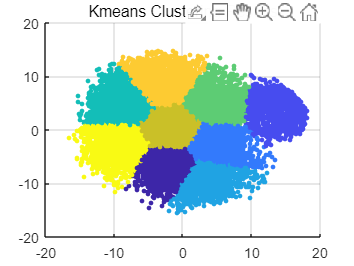


% 使用kmeans进行聚类
k = 9; % 聚类数
[cluster_idx_kmeans, ~] = kmeans(low_dim_data, k);
figure;
scatter(low_dim_data(:, 1), low_dim_data(:, 2), 10, cluster_idx_kmeans, 'filled');
grid on
title('Kmeans Clustering Results');

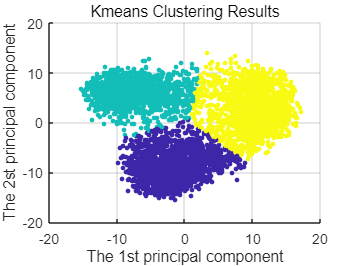


xlabel('The 1st principal component');
ylabel('The 2st principal component');


% 计算轮廓系数
silhouette_kmeans = silhouette(low_dim_data, cluster_idx_kmeans);
avg_silhouette_kmeans = mean(silhouette_kmeans);
disp(['K-means 聚类的平均轮廓系数: ', num2str(avg_silhouette_kmeans)]);

K-means 聚类的平均轮廓系数: 0.7774


cluster_labels = cluster_idx_kmeans;
true_labels = groundTruth;
% 假设 cluster_labels 和 true_labels 已经准备好
% 这里 cluster_labels 是聚类后的标签，true_labels 是真实标签

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 初始化映射关系的容器
mapping = zeros(size(unique_cluster_labels));

% 获取唯一的真实标签
unique_true_labels = unique(true_labels);

% 遍历每个聚类标签
for i = 1:length(unique_cluster_labels)
    current_cluster_label = unique_cluster_labels(i);
    
    % 找出当前聚类标签对应的所有样本点
    indices = cluster_labels == current_cluster_label;
    
    % 获取这些样本点的真实标签
    current_true_labels = true_labels(indices);
    
    % 统计当前聚类中每个真实标签的出现次数
    label_counts = histc(current_true_labels, unique_true_labels);
    
    % 选择出现次数最多的真实标签作为映射
    [~, max_count_idx] = max(label_counts);
    mapping(i) = unique_true_labels(max_count_idx);
end

% 显示映射结果
disp(mapping);

     3
     2
     1



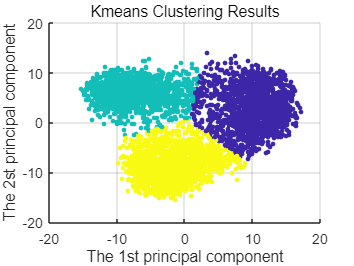

Accuracy: 93.76%



% 假设 cluster_labels、true_labels 和 mapping 已经准备好

% 创建一个新的数组来存储重新贴标签的结果
relabelled_cluster_labels = zeros(size(cluster_labels));

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 遍历所有数据点
for i = 1:length(cluster_labels)
    % 获取当前数据点的聚类标签
    current_cluster_label = cluster_labels(i);
    
    % 找到当前聚类标签在 unique_cluster_labels 中的索引
    cluster_label_index = find(unique_cluster_labels == current_cluster_label);

    % 获取映射后的真实标签
    mapped_label = mapping(cluster_label_index);

    % 更新重新贴标签的数组
    relabelled_cluster_labels(i) = mapped_label;
end

% 绘制kmeans的聚类结果
figure;

scatter(low_dim_data(:, 1), low_dim_data(:, 2), 10,  relabelled_cluster_labels, 'filled');
grid on
title('Kmeans Clustering Results');
xlabel('The 1st principal component');
ylabel('The 2st principal component');
accuracy = sum(groundTruth == relabelled_cluster_labels) / length(groundTruth);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

绘制层次聚类

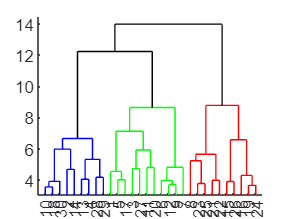

% 使用层次聚类进行聚类
k = 3;
Z = linkage(low_dim_data, 'average','chebychev');
cluster_idx_hierarchical = cluster(Z, 'maxclust', k);
cutoff = median([Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)








% 计算轮廓系数
silhouette_hierarchical = silhouette(low_dim_data, cluster_idx_hierarchical);
avg_silhouette_hierarchical = mean(silhouette_hierarchical);
disp(['层次聚类的平均轮廓系数: ', num2str(avg_silhouette_hierarchical)]);

层次聚类的平均轮廓系数: 0.62017




true_labels = groundTruth;
cluster_labels =cluster_idx_hierarchical;
% 假设 cluster_labels 和 true_labels 已经准备好
% 这里 cluster_labels 是聚类后的标签，true_labels 是真实标签

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 初始化映射关系的容器
mapping = zeros(size(unique_cluster_labels));

% 获取唯一的真实标签
unique_true_labels = unique(true_labels);

% 遍历每个聚类标签
for i = 1:length(unique_cluster_labels)
    current_cluster_label = unique_cluster_labels(i);
    
    % 找出当前聚类标签对应的所有样本点
    indices = cluster_labels == current_cluster_label;
    
    % 获取这些样本点的真实标签
    current_true_labels = true_labels(indices);
    
    % 统计当前聚类中每个真实标签的出现次数
    label_counts = histc(current_true_labels, unique_true_labels);
    
    % 选择出现次数最多的真实标签作为映射
    [~, max_count_idx] = max(label_counts);
    mapping(i) = unique_true_labels(max_count_idx);
end

% 显示映射结果
disp(mapping);

     3
     1
     2



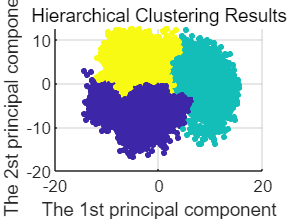


% 假设 cluster_labels、true_labels 和 mapping 已经准备好

% 创建一个新的数组来存储重新贴标签的结果
relabelled_cluster_labels = zeros(size(cluster_labels));

% 获取唯一的聚类标签列表
unique_cluster_labels = unique(cluster_labels);

% 遍历所有数据点
for i = 1:length(cluster_labels)
    % 获取当前数据点的聚类标签
    current_cluster_label = cluster_labels(i);
    
    % 找到当前聚类标签在 unique_cluster_labels 中的索引
    cluster_label_index = find(unique_cluster_labels == current_cluster_label);

    % 获取映射后的真实标签
    mapped_label = mapping(cluster_label_index);

    % 更新重新贴标签的数组
    relabelled_cluster_labels(i) = mapped_label;
end





% 绘制层次聚类的聚类结果
figure;
scatter(low_dim_data(:, 1), low_dim_data(:, 2), 10, relabelled_cluster_labels, 'filled');
title('Hierarchical Clustering Results');
xlabel('The 1st principal component');
ylabel('The 2st principal component');
grid on

accuracy = sum(groundTruth == relabelled_cluster_labels) / length(groundTruth);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 88.53%
